clear all
syms lambda rA rB R1 R2 R3 uA3 uB3 ;

r1=[5.827;2.870;11.960];
u31=[0.630;-0.496;0.598];
r2=[6.259;-2.258;19.135];
u32=[0.630;-0.496;0.598];
r3=[4.761;4.932;19.135];
u33=[0.630;-0.496;0.598];
r4=[7.573;7.125;8.770];
u34=[0.630;-0.496;0.598];
r5=[9.071;-0.065;8.770];
u35=[0.630;-0.496;0.598];
r6=[-1.081;-2.258;19.135];
u36=[0.630;-0.496;0.598];
r7=[-2.579;4.932;19.135];
u37=[0.630;-0.496;0.598];
r8=[0.233;7.125;8.770];
u38=[0.630;-0.496;0.598];
r9=[1.731;-0.065;8.770];
u39=[0.630;-0.496;0.598];
r10=[8.639;5.062;1.595];
u310=[0.630;-0.496;0.598];
r11=[-1.513;2.870;11.960];
u311=[0.630;-0.496;0.598];
r12=[4.329;10.060;11.960];
u312=[0.630;-0.496;0.598];

x1=[];
y1=[];
x2=[];
y2=[];
x3=[];
y3=[];
x4=[];
y4=[];
x5=[];
y5=[];
x6=[];
y6=[];
x7=[];
y7=[];
x8=[];
y8=[];
x9=[];
y9=[];
x10=[];
y10=[];
x11=[];
y11=[];

hold on 
axis([0 15 0 15]);
for R1=3:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r2,R1,R3,u31,u32);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r2,R1,R3,u31,u32);
    end
    [R1,R3,miu2]
    x1=[x1,R1];
    y1=[y1,R3];   
end

ans =     3.0000    7.3000    1.0001


ans =     3.3000    5.8000    1.0059


ans =     3.6000    5.1500    1.0059


ans =     3.9000    4.7500    1.0110


ans =     4.2000    4.5000    1.0127


ans =     4.5000    4.3500    1.0063


ans =     4.8000    4.2000    1.0137


ans =     5.1000    4.1000    1.0150


ans =     5.4000    4.0500    1.0052


ans =     5.7000    4.0000    1.0005


ans =     6.0000    3.9500    1.0000


ans =     6.3000    3.9000    1.0032


ans =     6.6000    3.8500    1.0096


ans =     6.9000    3.8000    1.0189


ans =     7.2000    3.8000    1.0072


ans =     7.5000    3.7500    1.0204


ans =     7.8000    3.7500    1.0112


ans =     8.1000    3.7500    1.0031


ans =     8.4000    3.7000    1.0203


ans =     8.7000    3.7000    1.0138


ans =     9.0000    3.7000    1.0079


ans =     9.3000    3.7000    1.0027


ans =     9.6000    3.6500    1.0234


ans =     9.9000    3.6500    1.0190


ans =    10.2000    3.6500    1.0151


ans =    10.5000    3.6500    1.0115


ans =    10.8000    3.6500    1.0082


ans =    11.1000    3.6500    1.0052


ans =    11.4000    3.6500    1.0024


ans =    11.7000    3.6000    1.0265


ans =    12.0000    3.6000    1.0242


ans =    12.3000    3.6000    1.0220


ans =    12.6000    3.6000    1.0200


ans =    12.9000    3.6000    1.0182



scatter(x1,y1,10,'markerfacecolor',[221, 42, 22]/256,...
        'markeredgecolor',[221, 42, 22]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','12')

for R1=3.6:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3]; 
end

ans =     3.6000    7.1000    1.0004


ans =     3.9000    3.0500    1.0051


ans =     4.2000    2.4000    1.0031


ans =     4.5000    2.1000    1.0013


ans =     4.8000    1.9000    1.0113


ans =     5.1000    1.8000    1.0028


ans =     5.4000    1.7000    1.0141


ans =     5.7000    1.6500    1.0063


ans =     6.0000    1.6000    1.0085


ans =     6.3000    1.5500    1.0199


ans =     6.6000    1.5000    1.0401


ans =     6.9000    1.5000    1.0160


ans =     7.2000    1.4500    1.0480


ans =     7.5000    1.4500    1.0295


ans =     7.8000    1.4500    1.0132


ans =     8.1000    1.4000    1.0579


ans = 1×3
    8.4000    1.4000    1.0451


ans = 1×3
    8.7000    1.4000    1.0336


ans = 1×3
    9.0000    1.4000    1.0234


ans = 1×3
    9.3000    1.4000    1.0142


ans = 1×3
    9.6000    1.4000    1.0060


ans = 1×3
    9.9000    1.3500    1.0652


ans = 1×3
   10.2000    1.3500    1.0586


ans = 1×3
   10.5000    1.3500    1.0526


ans = 1×3
   10.8000    1.3500    1.0473


ans = 1×3
   11.1000    1.3500    1.0424


ans = 1×3
   11.4000    1.3500    1.0381


ans = 1×3
   11.7000    1.3500    1.0341


ans = 1×3
   12.0000    1.3500    1.0306


ans = 1×3
   12.3000    1.3500    1.0274


ans = 1×3
   12.6000    1.3500    1.0245


ans = 1×3
   12.9000    1.3500    1.0220



for R3=3:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r3,R1,R3,u31,u33);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r3,R1,R3,u31,u33);
    end
    [R1,R3,miu2]
    x2=[x2,R1];
    y2=[y2,R3]; 
end

ans = 1×3
    3.9000    3.0000    1.0112


ans = 1×3
    3.8500    3.3000    1.0002


ans = 1×3
    3.7500    3.6000    1.0212


ans = 1×3
    3.7500    3.9000    1.0020


ans = 1×3
    3.7000    4.2000    1.0109


ans = 1×3
    3.6500    4.5000    1.0239


ans = 1×3
    3.6500    4.8000    1.0138


ans = 1×3
    3.6500    5.1000    1.0055


ans = 1×3
    3.6000    5.4000    1.0248


ans = 1×3
    3.6000    5.7000    1.0189


ans = 1×3
    3.6000    6.0000    1.0138


ans = 1×3
    3.6000    6.3000    1.0094


ans = 1×3
    3.6000    6.6000    1.0057


ans = 1×3
    3.6000    6.9000    1.0024


ans = 1×3
    3.5500    7.2000    1.0269


ans = 1×3
    3.5500    7.5000    1.0244


ans = 1×3
    3.5500    7.8000    1.0221


ans = 1×3
    3.5500    8.1000    1.0201


ans = 1×3
    3.5500    8.4000    1.0183


ans = 1×3
    3.5500    8.7000    1.0167


ans = 1×3
    3.5500    9.0000    1.0152


ans = 1×3
    3.5500    9.3000    1.0139


ans = 1×3
    3.5500    9.6000    1.0127


ans = 1×3
    3.5500    9.9000    1.0116


scatter(x2,y2,10,'markerfacecolor',[29, 50, 67]/256,...
        'markeredgecolor',[29, 50, 67]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','13')

for R3=1.6:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans = 1×3
    5.8500    1.6000    1.0007


ans = 1×3
    3.7000    1.9000    1.0066


ans = 1×3
    3.1500    2.2000    1.0147


ans = 1×3
    2.9000    2.5000    1.0188


ans = 1×3
    2.7500    2.8000    1.0257


ans = 1×3
    2.7000    3.1000    1.0039


ans = 1×3
    2.6000    3.4000    1.0279


ans = 1×3
    2.5500    3.7000    1.0327


ans = 1×3
    2.5500    4.0000    1.0102


ans = 1×3
    2.5000    4.3000    1.0277


ans = 1×3
    2.5000    4.6000    1.0132


ans = 1×3
    2.5000    4.9000    1.0013


ans = 1×3
    2.4500    5.2000    1.0290


ans = 1×3
    2.4500    5.5000    1.0206


ans = 1×3
    2.4500    5.8000    1.0135


ans = 1×3
    2.4500    6.1000    1.0075


ans = 1×3
    2.4500    6.4000    1.0022


ans = 1×3
    2.4000    6.7000    1.0377


ans = 1×3
    2.4000    7.0000    1.0337


ans = 1×3
    2.4000    7.3000    1.0302


ans = 1×3
    2.4000    7.6000    1.0271


ans = 1×3
    2.4000    7.9000    1.0244


ans = 1×3
    2.4000    8.2000    1.0219


ans = 1×3
    2.4000    8.5000    1.0197


ans = 1×3
    2.4000    8.8000    1.0178


ans = 1×3
    2.4000    9.1000    1.0160


ans = 1×3
    2.4000    9.4000    1.0144


ans = 1×3
    2.4000    9.7000    1.0129


ans = 1×3
    2.4000   10.0000    1.0116


%将曲线完善
for R1=2.7:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r4,R1,R3,u31,u34);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r4,R1,R3,u31,u34);
    end
    [R1,R3,miu2]
    x3=[x3,R1];
    y3=[y3,R3];  
end

ans = 1×3
    2.7000    3.1000    1.0039


ans = 1×3
    3.0000    2.4000    1.0033


ans = 1×3
    3.3000    2.1000    1.0066


ans = 1×3
    3.6000    1.9500    1.0002


ans = 1×3
    3.9000    1.8000    1.0325


ans = 1×3
    4.2000    1.7500    1.0192


ans = 1×3
    4.5000    1.7000    1.0193


ans = 1×3
    4.8000    1.6500    1.0308


ans = 1×3
    5.1000    1.6500    1.0028


ans = 1×3
    5.4000    1.6000    1.0292


ans = 1×3
    5.7000    1.6000    1.0095


ans = 1×3
    6.0000    1.5500    1.0476


ans = 1×3
    6.3000    1.5500    1.0332


ans = 1×3
    6.6000    1.5500    1.0208


ans = 1×3
    6.9000    1.5500    1.0100


ans = 1×3
    7.2000    1.5500    1.0007


ans = 1×3
    7.5000    1.5000    1.0533


ans = 1×3
    7.8000    1.5000    1.0461


ans = 1×3
    8.1000    1.5000    1.0398


ans = 1×3
    8.4000    1.5000    1.0343


ans = 1×3
    8.7000    1.5000    1.0294


ans = 1×3
    9.0000    1.5000    1.0250


ans = 1×3
    9.3000    1.5000    1.0212


ans = 1×3
    9.6000    1.5000    1.0177


ans = 1×3
    9.9000    1.5000    1.0147


ans = 1×3
   10.2000    1.5000    1.0120


ans = 1×3
   10.5000    1.5000    1.0096


ans = 1×3
   10.8000    1.5000    1.0075


ans = 1×3
   11.1000    1.5000    1.0056


ans = 1×3
   11.4000    1.5000    1.0040


ans = 1×3
   11.7000    1.5000    1.0025


ans = 1×3
   12.0000    1.5000    1.0013


ans = 1×3
   12.3000    1.5000    1.0002


ans = 1×3
   12.6000    1.4500    1.0682


ans = 1×3
   12.9000    1.4500    1.0675



scatter(x3,y3,10,'markerfacecolor',[63, 125, 162]/256,...
        'markeredgecolor',[63, 125, 162]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','14')

for R3=1:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r5,R1,R3,u31,u35);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r5,R1,R3,u31,u35);
    end
    [R1,R3,miu2]
    x4=[x4,R1];
    y4=[y4,R3];  
end

ans = 1×3
    4.2500    1.0000    1.0068


ans = 1×3
    3.2500    1.3000    1.0091


ans = 1×3
    2.9500    1.6000    1.0169


ans = 1×3
    2.8000    1.9000    1.0295


ans = 1×3
    2.7500    2.2000    1.0162


ans = 1×3
    2.7000    2.5000    1.0197


ans = 1×3
    2.6500    2.8000    1.0342


ans = 1×3
    2.6500    3.1000    1.0193


ans = 1×3
    2.6500    3.4000    1.0082


ans = 1×3
    2.6000    3.7000    1.0367


ans = 1×3
    2.6000    4.0000    1.0300


ans = 1×3
    2.6000    4.3000    1.0247


ans = 1×3
    2.6000    4.6000    1.0203


ans = 1×3
    2.6000    4.9000    1.0168


ans = 1×3
    2.6000    5.2000    1.0138


ans = 1×3
    2.6000    5.5000    1.0113


ans = 1×3
    2.6000    5.8000    1.0092


ans = 1×3
    2.6000    6.1000    1.0074


ans = 1×3
    2.6000    6.4000    1.0059


ans = 1×3
    2.6000    6.7000    1.0045


ans = 1×3
    2.6000    7.0000    1.0033


ans = 1×3
    2.6000    7.3000    1.0023


ans = 1×3
    2.6000    7.6000    1.0014


ans = 1×3
    2.6000    7.9000    1.0005


ans = 1×3
    2.5500    8.2000    1.0390


ans = 1×3
    2.5500    8.5000    1.0384


ans = 1×3
    2.5500    8.8000    1.0378


ans = 1×3
    2.5500    9.1000    1.0373


ans = 1×3
    2.5500    9.4000    1.0368


ans = 1×3
    2.5500    9.7000    1.0364


ans = 1×3
    2.5500   10.0000    1.0360



scatter(x4,y4,10,'markerfacecolor',[239, 193, 48]/256,...
        'markeredgecolor',[239, 193, 48]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','15')

for R3=1.6:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans = 1×3
    8.7000    1.6000    1.0002


ans = 1×3
    7.2000    1.9000    1.0035


ans = 1×3
    6.6000    2.2000    1.0037


ans = 1×3
    6.2500    2.5000    1.0105


ans = 1×3
    6.0500    2.8000    1.0117


ans = 1×3
    5.9500    3.1000    1.0031


ans = 1×3
    5.8500    3.4000    1.0051


ans = 1×3
    5.7500    3.7000    1.0149


ans = 1×3
    5.7000    4.0000    1.0145


ans = 1×3
    5.7000    4.3000    1.0016


ans = 1×3
    5.6500    4.6000    1.0074


ans = 1×3
    5.6000    4.9000    1.0155


ans = 1×3
    5.6000    5.2000    1.0083


ans = 1×3
    5.6000    5.5000    1.0023


ans = 1×3
    5.5500    5.8000    1.0143


ans = 1×3
    5.5500    6.1000    1.0100


ans = 1×3
    5.5500    6.4000    1.0062


ans = 1×3
    5.5500    6.7000    1.0029


ans = 1×3
    5.5000    7.0000    1.0177


ans = 1×3
    5.5000    7.3000    1.0152


ans = 1×3
    5.5000    7.6000    1.0129


ans = 1×3
    5.5000    7.9000    1.0109


ans = 1×3
    5.5000    8.2000    1.0092


ans = 1×3
    5.5000    8.5000    1.0076


ans = 1×3
    5.5000    8.8000    1.0061


ans = 1×3
    5.5000    9.1000    1.0049


ans = 1×3
    5.5000    9.4000    1.0037


ans = 1×3
    5.5000    9.7000    1.0026


ans = 1×3
    5.5000   10.0000    1.0017



for R1=6:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r6,R1,R3,u31,u36);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r6,R1,R3,u31,u36);
    end
    [R1,R3,miu2]
    x5=[x5,R1];
    y5=[y5,R3];  
end

ans = 1×3
    6.0000    2.9500    1.0058


ans = 1×3
    6.3000    2.4500    1.0086


ans = 1×3
    6.6000    2.2000    1.0037


ans = 1×3
    6.9000    2.0000    1.0127


ans = 1×3
    7.2000    1.9000    1.0035


ans = 1×3
    7.5000    1.8000    1.0077


ans = 1×3
    7.8000    1.7000    1.0260


ans = 1×3
    8.1000    1.6500    1.0237


ans = 1×3
    8.4000    1.6000    1.0285


ans = 1×3
    8.7000    1.6000    1.0002


ans = 1×3
    9.0000    1.5500    1.0147


ans = 1×3
    9.3000    1.5000    1.0360


ans = 1×3
    9.6000    1.5000    1.0153


ans = 1×3
    9.9000    1.4500    1.0456


ans = 1×3
   10.2000    1.4500    1.0285


ans = 1×3
   10.5000    1.4500    1.0129


ans = 1×3
   10.8000    1.4000    1.0535


ans = 1×3
   11.1000    1.4000    1.0406


ans = 1×3
   11.4000    1.4000    1.0288


ans = 1×3
   11.7000    1.4000    1.0179


ans = 1×3
   12.0000    1.4000    1.0079


ans = 1×3
   12.3000    1.3500    1.0605


ans = 1×3
   12.6000    1.3500    1.0522


ans = 1×3
   12.9000    1.3500    1.0445


scatter(x5,y5,10,'markerfacecolor',[151, 150, 159]/256,...
        'markeredgecolor',[151, 150, 159]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','16')

for R3=1.6:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r7,R1,R3,u31,u37);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r7,R1,R3,u31,u37);
    end
    [R1,R3,miu2]
    x6=[x6,R1];
    y6=[y6,R3];  
end

ans = 1×3
    7.1500    1.6000    1.0015


ans = 1×3
    6.5000    1.9000    1.0091


ans = 1×3
    6.2000    2.2000    1.0080


ans = 1×3
    6.0000    2.5000    1.0138


ans = 1×3
    5.9000    2.8000    1.0094


ans = 1×3
    5.8500    3.1000    1.0003


ans = 1×3
    5.7500    3.4000    1.0136


ans = 1×3
    5.7000    3.7000    1.0160


ans = 1×3
    5.7000    4.0000    1.0052


ans = 1×3
    5.6500    4.3000    1.0132


ans = 1×3
    5.6500    4.6000    1.0062


ans = 1×3
    5.6500    4.9000    1.0005


ans = 1×3
    5.6000    5.2000    1.0128


ans = 1×3
    5.6000    5.5000    1.0088


ans = 1×3
    5.6000    5.8000    1.0054


ans = 1×3
    5.6000    6.1000    1.0024


ans = 1×3
    5.5500    6.4000    1.0176


ans = 1×3
    5.5500    6.7000    1.0154


ans = 1×3
    5.5500    7.0000    1.0134


ans = 1×3
    5.5500    7.3000    1.0118


ans = 1×3
    5.5500    7.6000    1.0103


ans = 1×3
    5.5500    7.9000    1.0089


ans = 1×3
    5.5500    8.2000    1.0078


ans = 1×3
    5.5500    8.5000    1.0067


ans = 1×3
    5.5500    8.8000    1.0057


ans = 1×3
    5.5500    9.1000    1.0049


ans = 1×3
    5.5500    9.4000    1.0041


ans = 1×3
    5.5500    9.7000    1.0034


ans = 1×3
    5.5500   10.0000    1.0027



scatter(x6,y6,10,'markerfacecolor',[237, 125, 49]/256,...
        'markeredgecolor',[237, 125, 49]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','17')

for R1=1.3:0.3:13 %离心率
    R3=6;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r8,R1,R3,u31,u38);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r8,R1,R3,u31,u38);
    end
    [R1,R3,miu2]
    x7=[x7,R1];
    y7=[y7,R3];  
end

ans = 1×3
    1.3000    4.8500    1.0040


ans = 1×3
    1.6000    4.3500    1.0151


ans = 1×3
    1.9000    4.1500    1.0125


ans = 1×3
    2.2000    4.0500    1.0062


ans = 1×3
    2.5000    3.9500    1.0192


ans = 1×3
    2.8000    3.9000    1.0208


ans = 1×3
    3.1000    3.9000    1.0050


ans = 1×3
    3.4000    3.8500    1.0176


ans = 1×3
    3.7000    3.8500    1.0085


ans = 1×3
    4.0000    3.8500    1.0015


ans = 1×3
    4.3000    3.8000    1.0212


ans = 1×3
    4.6000    3.8000    1.0167


ans = 1×3
    4.9000    3.8000    1.0129


ans = 1×3
    5.2000    3.8000    1.0098


ans = 1×3
    5.5000    3.8000    1.0072


ans = 1×3
    5.8000    3.8000    1.0050


ans = 1×3
    6.1000    3.8000    1.0032


ans = 1×3
    6.4000    3.8000    1.0016


ans = 1×3
    6.7000    3.8000    1.0002


ans = 1×3
    7.0000    3.7500    1.0255


ans = 1×3
    7.3000    3.7500    1.0245


ans = 1×3
    7.6000    3.7500    1.0236


ans = 1×3
    7.9000    3.7500    1.0228


ans = 1×3
    8.2000    3.7500    1.0221


ans = 1×3
    8.5000    3.7500    1.0215


ans = 1×3
    8.8000    3.7500    1.0210


ans = 1×3
    9.1000    3.7500    1.0205


ans = 1×3
    9.4000    3.7500    1.0201


ans = 1×3
    9.7000    3.7500    1.0197


ans = 1×3
   10.0000    3.7500    1.0194


ans = 1×3
   10.3000    3.7500    1.0191


ans = 1×3
   10.6000    3.7500    1.0189


ans = 1×3
   10.9000    3.7500    1.0187


ans = 1×3
   11.2000    3.7500    1.0185


ans = 1×3
   11.5000    3.7500    1.0184


ans = 1×3
   11.8000    3.7500    1.0183


ans = 1×3
   12.1000    3.7500    1.0181


ans = 1×3
   12.4000    3.7500    1.0181


ans = 1×3
   12.7000    3.7500    1.0180


ans = 1×3
   13.0000    3.7500    1.0180



scatter(x7,y7,10,'markerfacecolor',[47, 85, 151]/256,...
        'markeredgecolor',[47, 85, 151]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','18')

for R3=1.6:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r9,R1,R3,u31,u39);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    [R1,R3,miu2]
    x8=[x8,R1];
    y8=[y8,R3];  
end

ans = 1×3
    8.2500    1.6000    1.0006


ans = 1×3
    4.2500    1.9000    1.0023


ans = 1×3
    3.5000    2.2000    1.0133


ans = 1×3
    3.2000    2.5000    1.0117


ans = 1×3
    3.0500    2.8000    1.0020


ans = 1×3
    2.9000    3.1000    1.0232


ans = 1×3
    2.8500    3.4000    1.0106


ans = 1×3
    2.8000    3.7000    1.0089


ans = 1×3
    2.7500    4.0000    1.0155


ans = 1×3
    2.7000    4.3000    1.0288


ans = 1×3
    2.7000    4.6000    1.0131


ans = 1×3
    2.7000    4.9000    1.0002


ans = 1×3
    2.6500    5.2000    1.0239


ans = 1×3
    2.6500    5.5000    1.0149


ans = 1×3
    2.6500    5.8000    1.0072


ans = 1×3
    2.6500    6.1000    1.0007


ans = 1×3
    2.6000    6.4000    1.0315


ans = 1×3
    2.6000    6.7000    1.0266


ans = 1×3
    2.6000    7.0000    1.0223


ans = 1×3
    2.6000    7.3000    1.0185


ans = 1×3
    2.6000    7.6000    1.0152


ans = 1×3
    2.6000    7.9000    1.0122


ans = 1×3
    2.6000    8.2000    1.0096


ans = 1×3
    2.6000    8.5000    1.0072


ans = 1×3
    2.6000    8.8000    1.0051


ans = 1×3
    2.6000    9.1000    1.0031


ans = 1×3
    2.6000    9.4000    1.0014


ans = 1×3
    2.5500    9.7000    1.0384


ans = 1×3
    2.5500   10.0000    1.0370



for R1=4:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r9,R1,R3,u31,u39);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r9,R1,R3,u31,u39);
    end
    [R1,R3,miu2]
    x8=[x8,R1];
    y8=[y8,R3];  
end

ans = 1×3
    4.0000    1.9500    1.0170


ans = 1×3
    4.3000    1.8500    1.0289


ans = 1×3
    4.6000    1.8000    1.0219


ans = 1×3
    4.9000    1.7500    1.0264


ans = 1×3
    5.2000    1.7000    1.0408


ans = 1×3
    5.5000    1.7000    1.0152


ans = 1×3
    5.8000    1.6500    1.0426


ans = 1×3
    6.1000    1.6500    1.0241


ans = 1×3
    6.4000    1.6500    1.0082


ans = 1×3
    6.7000    1.6000    1.0485


ans = 1×3
    7.0000    1.6000    1.0365


ans = 1×3
    7.3000    1.6000    1.0261


ans = 1×3
    7.6000    1.6000    1.0169


ans = 1×3
    7.9000    1.6000    1.0089


ans = 1×3
    8.2000    1.6000    1.0017


ans = 1×3
    8.5000    1.5500    1.0551


ans = 1×3
    8.8000    1.5500    1.0496


ans = 1×3
    9.1000    1.5500    1.0446


ans = 1×3
    9.4000    1.5500    1.0402


ans = 1×3
    9.7000    1.5500    1.0362


ans = 1×3
   10.0000    1.5500    1.0327


ans = 1×3
   10.3000    1.5500    1.0296


ans = 1×3
   10.6000    1.5500    1.0268


ans = 1×3
   10.9000    1.5500    1.0243


ans = 1×3
   11.2000    1.5500    1.0220


ans = 1×3
   11.5000    1.5500    1.0201


ans = 1×3
   11.8000    1.5500    1.0183


ans = 1×3
   12.1000    1.5500    1.0168


ans = 1×3
   12.4000    1.5500    1.0154


ans = 1×3
   12.7000    1.5500    1.0142


ans = 1×3
   13.0000    1.5500    1.0132


scatter(x8,y8,10,'markerfacecolor',[84, 130, 53]/256,...
        'markeredgecolor',[84, 130, 53]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','19')

for R3=3:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r10,R1,R3,u31,u310);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    [R1,R3,miu2]
    x9=[x9,R1];
    y9=[y9,R3];  
end

ans = 1×3
   12.1000    3.0000    1.0009


ans = 1×3
    8.6000    3.3000    1.0022


ans = 1×3
    7.3500    3.6000    1.0022


ans = 1×3
    6.6500    3.9000    1.0072


ans = 1×3
    6.2500    4.2000    1.0053


ans = 1×3
    5.9500    4.5000    1.0091


ans = 1×3
    5.7500    4.8000    1.0085


ans = 1×3
    5.6000    5.1000    1.0076


ans = 1×3
    5.5000    5.4000    1.0023


ans = 1×3
    5.4000    5.7000    1.0033


ans = 1×3
    5.3000    6.0000    1.0098


ans = 1×3
    5.2500    6.3000    1.0055


ans = 1×3
    5.2000    6.6000    1.0042


ans = 1×3
    5.1500    6.9000    1.0056


ans = 1×3
    5.1000    7.2000    1.0092


ans = 1×3
    5.0500    7.5000    1.0149


ans = 1×3
    5.0500    7.8000    1.0047


ans = 1×3
    5.0000    8.1000    1.0133


ans = 1×3
    5.0000    8.4000    1.0052


ans = 1×3
    4.9500    8.7000    1.0161


ans = 1×3
    4.9500    9.0000    1.0095


ans = 1×3
    4.9500    9.3000    1.0036


ans = 1×3
    4.9000    9.6000    1.0169


ans = 1×3
    4.9000    9.9000    1.0120



for R1=5:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r10,R1,R3,u31,u310);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r10,R1,R3,u31,u310);
    end
    [R1,R3,miu2]
    x9=[x9,R1];
    y9=[y9,R3];  
end

ans = 1×3
    5.0000    8.6000    1.0002


ans = 1×3
    5.3000    6.1000    1.0030


ans = 1×3
    5.6000    5.1500    1.0020


ans = 1×3
    5.9000    4.6000    1.0037


ans = 1×3
    6.2000    4.2500    1.0045


ans = 1×3
    6.5000    4.0000    1.0062


ans = 1×3
    6.8000    3.8000    1.0118


ans = 1×3
    7.1000    3.7000    1.0006


ans = 1×3
    7.4000    3.5500    1.0132


ans = 1×3
    7.7000    3.4500    1.0175


ans = 1×3
    8.0000    3.4000    1.0087


ans = 1×3
    8.3000    3.3500    1.0037


ans = 1×3
    8.6000    3.3000    1.0022


ans = 1×3
    8.9000    3.2500    1.0039


ans = 1×3
    9.2000    3.2000    1.0086


ans = 1×3
    9.5000    3.1500    1.0161


ans = 1×3
    9.8000    3.1500    1.0012


ans = 1×3
   10.1000    3.1000    1.0127


ans = 1×3
   10.4000    3.1000    1.0003


ans = 1×3
   10.7000    3.0500    1.0153


ans = 1×3
   11.0000    3.0500    1.0049


ans = 1×3
   11.3000    3.0000    1.0229


ans = 1×3
   11.6000    3.0000    1.0141


ans = 1×3
   11.9000    3.0000    1.0060


ans = 1×3
   12.2000    2.9500    1.0276


ans = 1×3
   12.5000    2.9500    1.0207


ans = 1×3
   12.8000    2.9500    1.0142


scatter(x9,y9,10,'markerfacecolor',[191, 144, 0]/256,...
        'markeredgecolor',[191, 144, 0]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','1,10')

for R3=2.4:0.3:10 %离心率
    R1=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r11,R1,R3,u31,u311);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1+n;
        R3=R3;
        miu2=cont(r1,r11,R1,R3,u31,u311);
    end
    
    while miu2<1
        R1=R1-n;
        R3=R3;
        miu2=cont(r1,r11,R1,R3,u31,u311);
    end
    [R1,R3,miu2]
    x10=[x10,R1];
    y10=[y10,R3];  
end

ans = 1×3
   10.9500    2.4000    1.0004


ans = 1×3
    5.5000    2.7000    1.0023


ans = 1×3
    4.4500    3.0000    1.0043


ans = 1×3
    3.9500    3.3000    1.0115


ans = 1×3
    3.7000    3.6000    1.0058


ans = 1×3
    3.5000    3.9000    1.0146


ans = 1×3
    3.4000    4.2000    1.0058


ans = 1×3
    3.3000    4.5000    1.0099


ans = 1×3
    3.2500    4.8000    1.0011


ans = 1×3
    3.1500    5.1000    1.0242


ans = 1×3
    3.1500    5.4000    1.0020


ans = 1×3
    3.1000    5.7000    1.0099


ans = 1×3
    3.0500    6.0000    1.0218


ans = 1×3
    3.0500    6.3000    1.0080


ans = 1×3
    3.0000    6.6000    1.0254


ans = 1×3
    3.0000    6.9000    1.0150


ans = 1×3
    3.0000    7.2000    1.0058


ans = 1×3
    2.9500    7.5000    1.0286


ans = 1×3
    2.9500    7.8000    1.0214


ans = 1×3
    2.9500    8.1000    1.0150


ans = 1×3
    2.9500    8.4000    1.0093


ans = 1×3
    2.9500    8.7000    1.0042


ans = 1×3
    2.9000    9.0000    1.0320


ans = 1×3
    2.9000    9.3000    1.0278


ans = 1×3
    2.9000    9.6000    1.0240


ans = 1×3
    2.9000    9.9000    1.0206



for R1=4:0.3:13 %离心率
    R3=4;
     %椭球半轴长，R1=R2,R3是polar axis
    n=0.05; %模拟的步长精度

    miu2=cont(r1,r11,R1,R3,u31,u311);
    %cont(rA,rB,R1,R3,uA3,uB3)
    while miu2>1
        R1=R1;
        R3=R3+n;
        miu2=cont(r1,r11,R1,R3,u31,u311);
    end
    
    while miu2<1
        R1=R1;
        R3=R3-n;
        miu2=cont(r1,r11,R1,R3,u31,u311);
    end
    [R1,R3,miu2]
    x10=[x10,R1];
    y10=[y10,R3];  
end

ans = 1×3
    4.0000    3.2500    1.0138


ans = 1×3
    4.3000    3.0500    1.0141


ans = 1×3
    4.6000    2.9000    1.0197


ans = 1×3
    4.9000    2.8000    1.0204


ans = 1×3
    5.2000    2.7500    1.0076


ans = 1×3
    5.5000    2.7000    1.0023


ans = 1×3
    5.8000    2.6500    1.0033


ans = 1×3
    6.1000    2.6000    1.0099


ans = 1×3
    6.4000    2.5500    1.0214


ans = 1×3
    6.7000    2.5500    1.0042


ans = 1×3
    7.0000    2.5000    1.0224


ans = 1×3
    7.3000    2.5000    1.0092


ans = 1×3
    7.6000    2.4500    1.0330


ans = 1×3
    7.9000    2.4500    1.0227


ans = 1×3
    8.2000    2.4500    1.0136


ans = 1×3
    8.5000    2.4500    1.0054


ans = 1×3
    8.8000    2.4000    1.0358


ans = 1×3
    9.1000    2.4000    1.0292


ans = 1×3
    9.4000    2.4000    1.0233


ans = 1×3
    9.7000    2.4000    1.0179


ans = 1×3
   10.0000    2.4000    1.0131


ans = 1×3
   10.3000    2.4000    1.0087


ans = 1×3
   10.6000    2.4000    1.0046


ans = 1×3
   10.9000    2.4000    1.0010


ans = 1×3
   11.2000    2.3500    1.0380


ans = 1×3
   11.5000    2.3500    1.0350


ans = 1×3
   11.8000    2.3500    1.0322


ans = 1×3
   12.1000    2.3500    1.0297


ans = 1×3
   12.4000    2.3500    1.0274


ans = 1×3
   12.7000    2.3500    1.0253


ans = 1×3
   13.0000    2.3500    1.0233


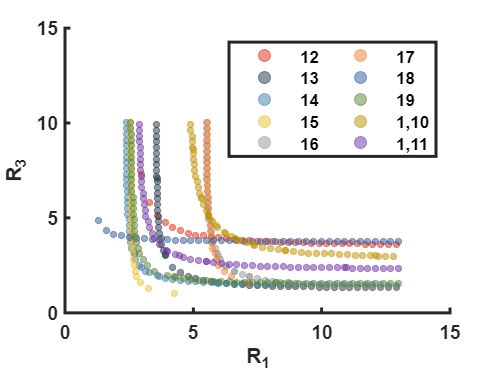


scatter(x10,y10,10,'markerfacecolor',[112, 48, 160]/256,...
        'markeredgecolor',[112, 48, 160]/256,...
        'markerfacealpha',.5,'markeredgealpha',.5,...
        'DisplayName','1,11')



set(gca,'linewidth',1.5,'FontWeight','bold','FontName','arial');
xlabel('R_1','FontName','arial','FontWeight','bold'); 
ylabel('R_3','FontName','arial','FontWeight','bold');
legend('Location','northeast','NumColumns',2);
hold off

function miu2=cont(rA,rB,R1,R3,uA3,uB3)
    syms lambda
    rAB=rB-rA;
    e=R3/R1;
    x=(1-lambda)*(1-e^2);
    y=lambda*(1-e^2);
    D=(1-x)*(1-y)-x*y*(dot(uA3,uB3))^2;
    alpha=x*(1-y)/D;
    beta=y*(1-x)/D;
    gama=x*y*(dot(uA3,uB3))/D;
    I=eye(3);
    C=(I+alpha*(uA3*uA3.')+beta*(uB3*uB3.')+gama*((uA3*uB3.')+(uB3*uA3.')))/(R1^2);
    F=lambda*(1-lambda)*(rAB.'*C*rAB);
    fun=@(lambda) -eval(F);
    [~,fval]=fminbnd(fun,0,1);
    miu2=-fval;
end

